# Lecture 7: Fourier Transform

# Part 3: Image FFT examples

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture7 - Fourier Transform

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
close all, clearvars, clc;

## 1. Displaying Fourier transforms of images

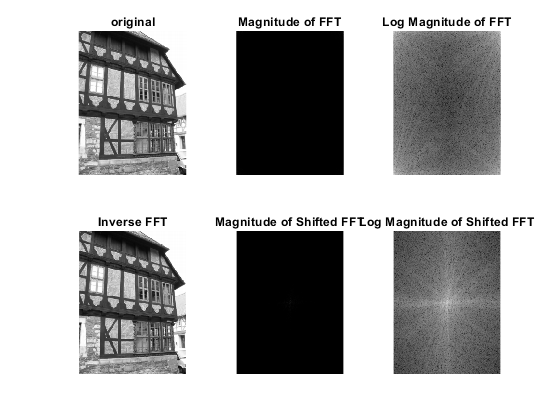

I=imread('images/test.tif'); %read image

F=fft2(I); %perform FFT
Fs=fftshift(F); %shift FFT spectrum to center DC coefficient
Iinv=ifft2(F); %inverse FFT (we use F not Fs in inverse transform)

% display original image
subplot(2,3,1); 
imshow(I);
title('original');

% display the fourier spectrum
subplot(2,3,2); 
imshow(abs(F),[]);
title('Magnitude of FFT');

% display the fourier spectrum using log trans.
subplot(2,3,3); 
imshow(log(1+abs(F)),[]);
title('Log Magnitude of FFT');

% display inverse FFT (it generates the original image)
subplot(2,3,4); 
imshow(Iinv,[]);
title('Inverse FFT');

% display the fourier spectrum of the shifted FFT
subplot(2,3,5); 
imshow(abs(Fs),[]);
title('Magnitude of Shifted FFT');

% display the fourier spectrum of the shifted FFT using log trans.
subplot(2,3,6); 
imshow(log(1+abs(Fs)),[]);
title('Log Magnitude of Shifted FFT');

## 2. Periodic image pattern examples

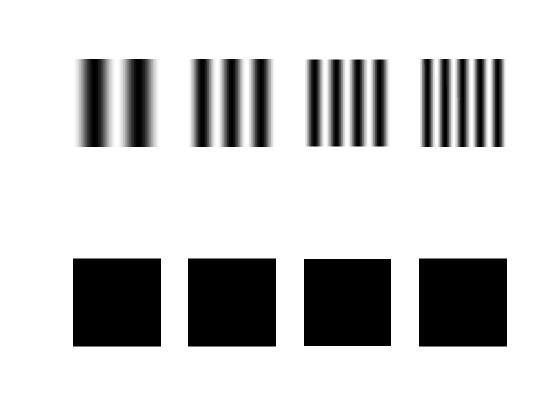

N = 128;
[x,y] = meshgrid(1:N,1:N);

% generate periodic test patterns
p1 = mat2gray(cos(2*pi*x/N*2));
p2 = mat2gray(cos(2*pi*x/N*3));
p3 = mat2gray(cos(2*pi*x/N*4));
p4 = mat2gray(cos(2*pi*x/N*5));

% calculate fourier transforms
p1f = log(1+abs(fftshift(fft2(p1))));
p2f = log(1+abs(fftshift(fft2(p2))));
p3f = log(1+abs(fftshift(fft2(p3))));
p4f = log(1+abs(fftshift(fft2(p4))));

% display
figure, subplot(2,4,1),imshow(p1)
subplot(2,4,2),imshow(p2)
subplot(2,4,3),imshow(p3)
subplot(2,4,4),imshow(p4)
subplot(2,4,5),imshow(p1f)
subplot(2,4,6),imshow(p2f)
subplot(2,4,7),imshow(p3f)
subplot(2,4,8),imshow(p4f)

## 3. Linearity of Fourier Transforms

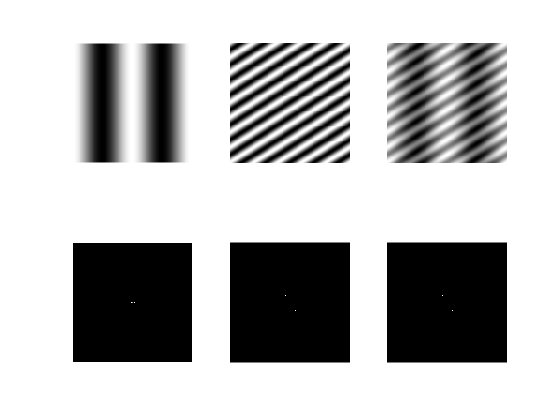

p5 = mat2gray(cos(2*pi*x/N*5 + 2*pi*y/N*8));
p6 = mat2gray(p1+p5);

p5f = log(1+abs(fftshift(fft2(p5))));
p6f = log(1+abs(fftshift(fft2(p6))));

figure, subplot(2,3,1),imshow(p1)
subplot(2,3,2),imshow(p5)
subplot(2,3,3),imshow(p6)
subplot(2,3,4),imshow(p1f)
subplot(2,3,5),imshow(p5f)
subplot(2,3,6),imshow(p6f)

## 3. Edge examples

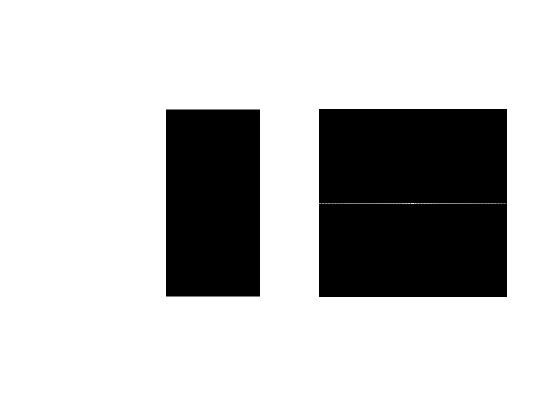

im = ones(256);
im(:,128:256) = 0; % generate a test image

imf = fft2(im); % Fourier transform of the input image
imfs = fftshift(imf); % Shift the transform

figure, subplot(1,2,1), imshow(im)
subplot(1,2,2), imshow(log(1+abs(imfs)),[]) % display the spectrum

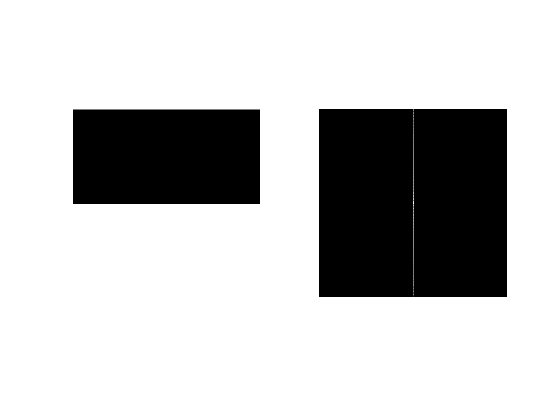

im2 = imrotate(im,90); % rotate the image

imf2 = fft2(im2); % Fourier transform of the rotated image
imfs2 = fftshift(imf2); % Shift the transform

figure, subplot(1,2,1),imshow(im2);
subplot(1,2,2),imshow(log(1+abs(imfs2)),[]) % display the spectrum